# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

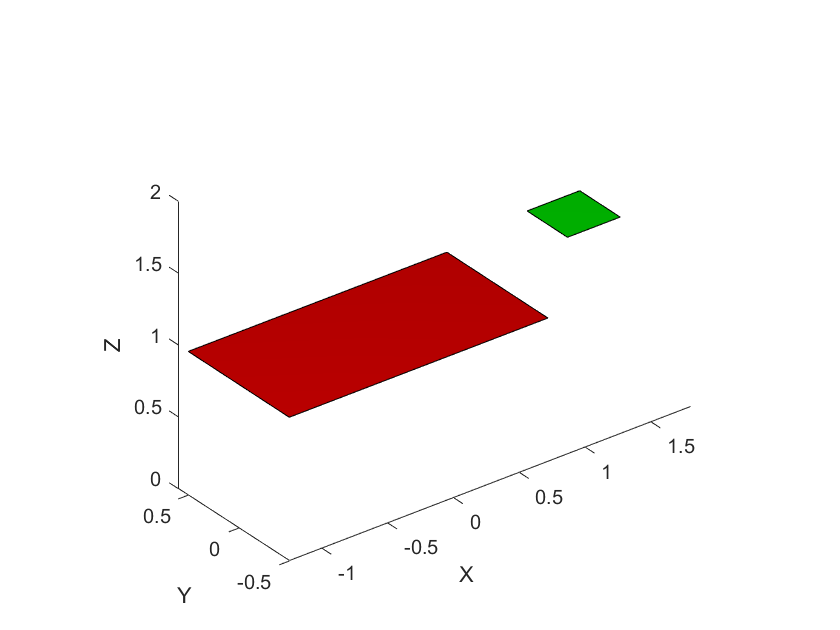

tool_offset = [0, 0, 0.1];
table_h = 1.0;
table_length = 2.5;
table_width = 1.0;
t1_x = [-table_length/2 table_length/3.5 table_length/3.5 -table_length/2];
t1_y = [-table_width/2 -table_width/2 table_width/2 table_width/2];
t1_z = [table_h table_h table_h table_h];

patch(t1_x,t1_y,t1_z,'red')

toolt_origin = [1.4 0.2 table_h];
toolt_size = [0.4 0.4 0];
t2_x = [toolt_origin(1) toolt_origin(1)+toolt_size(1) toolt_origin(1)+toolt_size(1) toolt_origin(1)];
t2_y = [toolt_origin(2) toolt_origin(2) toolt_origin(2)+toolt_size(2) toolt_origin(2)+toolt_size(2)];
t2_z = [toolt_origin(3) toolt_origin(3) toolt_origin(3) toolt_origin(3)];

patch(t2_x,t2_y,t2_z,'green')

axis([-2 2 -2 2 0 4]), axis('equal');
camlight('headlight');
material('dull');
xlabel('X'), ylabel('Y'), zlabel('Z')
hold on

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

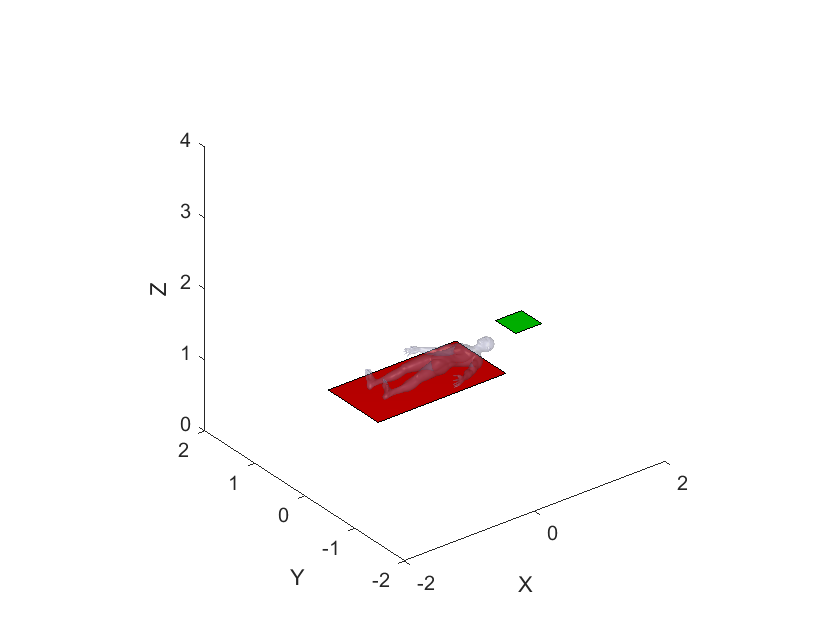

[VB,FB] = readOBJ('Human_body.obj','Quads',true);
person_height = 1.8;
VB = VB .* (person_height/max(VB(:, 2)));
VB = [VB ones(size(VB, 1), 1)];
VB = transl(-person_height/2, 0, table_h-min(VB(:, 3)))*trotz(-90, 'deg')*VB';
VB = (VB(1:3, :))';
p = patch('Faces',FB,'Vertices',VB, 'FaceColor',       [0.8 0.8 1.0], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15, ...
         'FaceAlpha', 0.25);
axis([-2 2 -2 2 0 4]);

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

## put your code Here

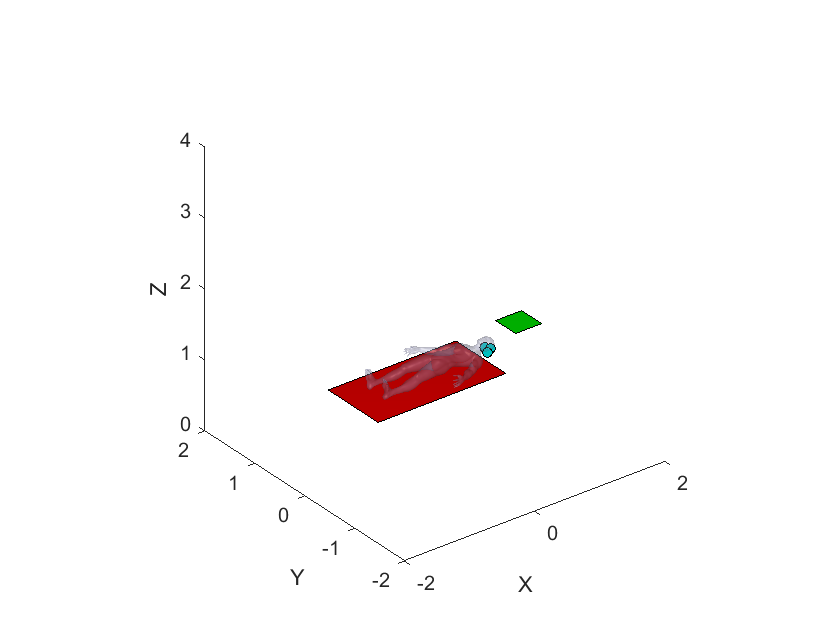

% [VS,FS] = stlRead('Crani.stl');
RFC = transl(person_height/2-0.11,-0.005,table_h+0.1425)*troty(90, 'deg')*trotz(-90, 'deg')*trscale(0.001);
% VS2 = h2e(RFC*e2h(VS'))';
% 
% p = patch('Faces',FS,'Vertices',VS2, 'FaceColor',       [0.2 1 0.2], ...
%          'EdgeColor',       'none',        ...
%          'FaceLighting',    'flat',     ...
%          'AmbientStrength', 0.95, ...
%          'FaceAlpha', 0.75);

RFI = RFC * trscale(1, 1, 1.4) * troty(180, 'deg') * transl(-125, -145, -65);
fiducidals = load('fiducidals.csv');
fiducidals = h2e(RFI * e2h(fiducidals'))';

scatter3(fiducidals(:, 1), fiducidals(:, 2), fiducidals(:, 3), 24, ...
    'MarkerEdgeColor','k', ...
    'MarkerFaceColor',[0 .75 .75])  

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

tumor = load('tumor.csv');


t_even = tumor(1:2:end, :);
t_odd = tumor(2:2:end, :);

t_n1 = [t_even(:, 1) t_odd(:, 2) t_even(:, 3)];
t_n2 = [t_odd(:, 1) t_even(:, 2) t_even(:, 3)];

tumor = [tumor; t_n1; t_n2];

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

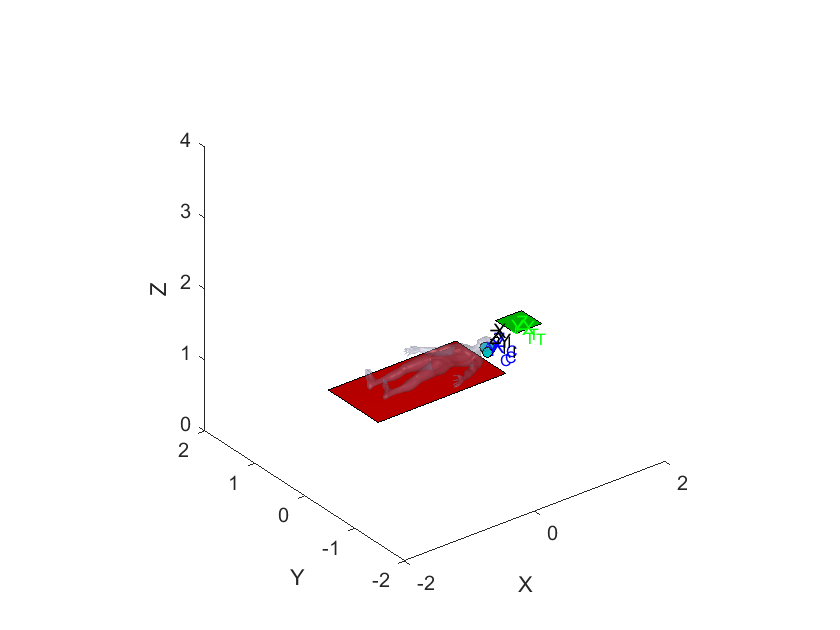

trplot(RFC, 'length', 100, 'color', 'b', 'frame', 'C')
trplot(RFI, 'length', 100, 'color', 'k', 'frame', 'I')

RFT = transl(toolt_origin);
trplot(RFT, 'length', 0.5, 'color', 'g', 'frame', 'T')


RFTPerson = transl(t1_x(1),t1_y(1),t1_z(1))
trplot(RFTPerson, 'length', 0.5, 'color', 'r', 'frame', 'TP')

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

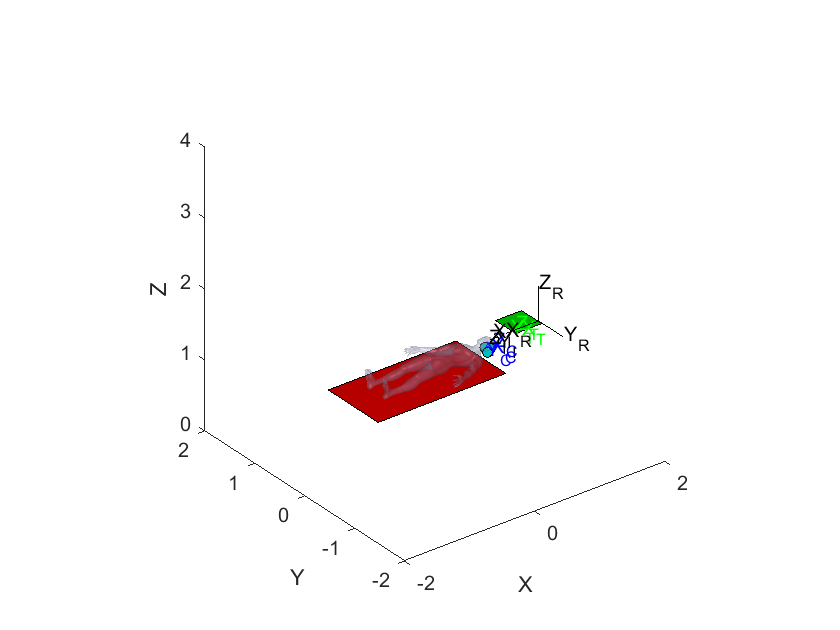

mdl_puma560
%EE=p560.fkine(qz)
RFR = transl(1.6, 0, 1.2) * trotz(180, 'deg');

p560.tool = SE3(tool_offset);
p560.base = RFR;
%p560.plot(qz, 'zoom', 2)

trplot(RFR, 'length', 0.5, 'color', 'k', 'frame', 'R')

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

% %tumor = h2e(RFI * e2h(tumor'))';
% 
% %tumor % RFI
% vIR = RFI(1:3, 4) - RFR(1:3, 4);
% rotIR = trotz(-90, 'deg') * trotx(-90, 'deg') * transl(-RFR(1:3, 4));
% %tumor_new = h2e(transl(dist) * transl(RFI(1:3, 4)) * trotz(-90, 'deg') * trotx(90, 'deg') * e2h(tumor'))'
% ItoR = transl(vIR) * rotIR
% tumorR = h2e(ItoR * e2h(tumor'))'
% tumor_new = h2e(RFR * trscale(0.001, 0.001, 0.001) * e2h(tumorR'))'

ItoR = inv(RFR) * RFI

ItoR =          0         0    0.0014    0.7190
   -0.0010         0         0    0.1300
         0   -0.0010         0    0.0875
         0         0         0    1.0000



% pointWI = h2e(RFI * e2h(tumor'))';
pointR = h2e(ItoR * e2h(tumor'))';
pointWR = h2e(RFR * e2h(pointR'))';
tumor = pointWR;

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

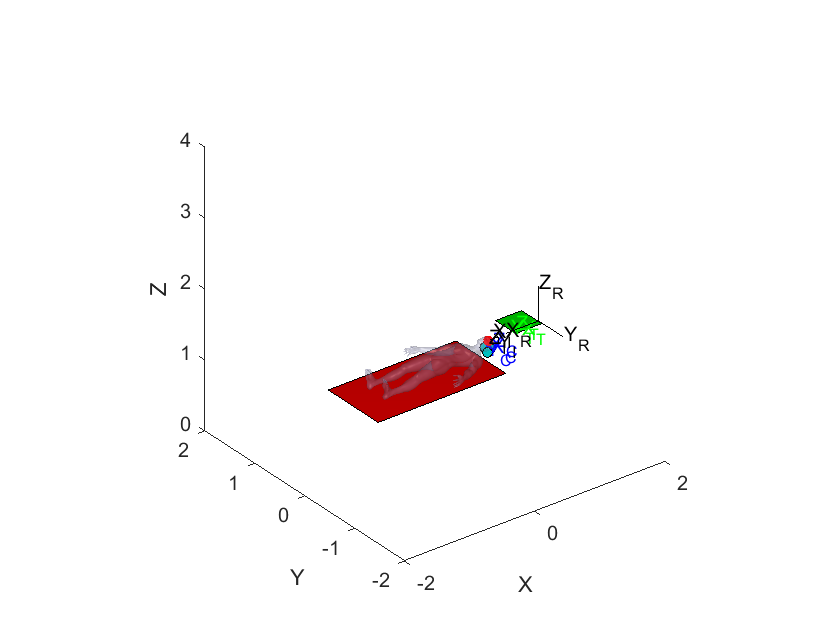

scatter3(pointWR(:, 1), pointWR(:, 2), pointWR(:, 3), 12, 'r', 'filled')

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

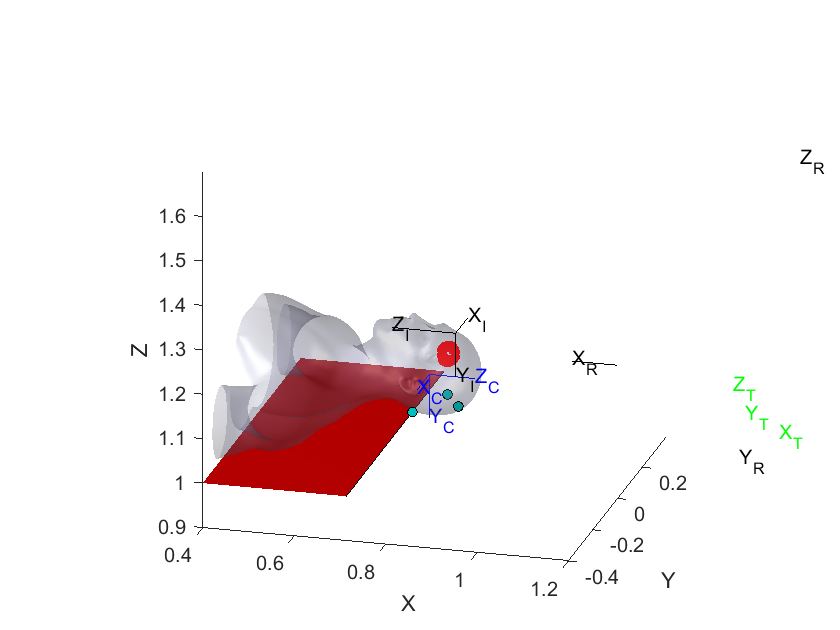

view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7])

% task_changeTool
% task_biopsy

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

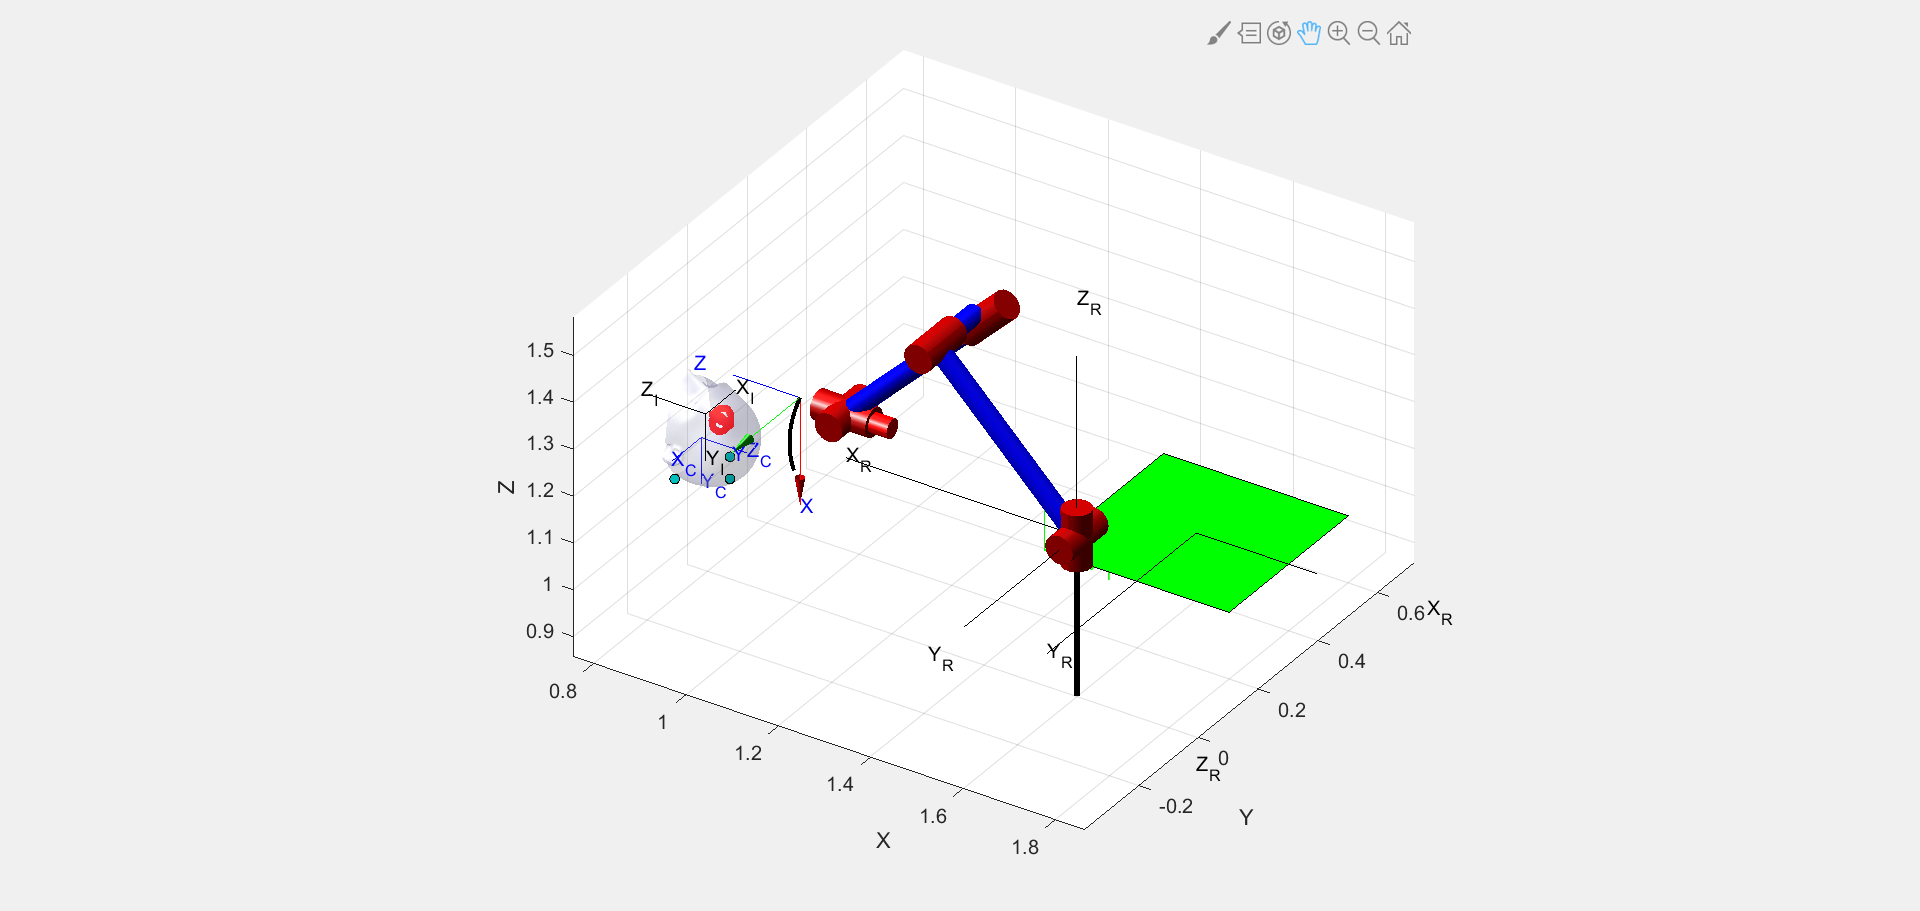

view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7])
task_changeTool
task_trepanation

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

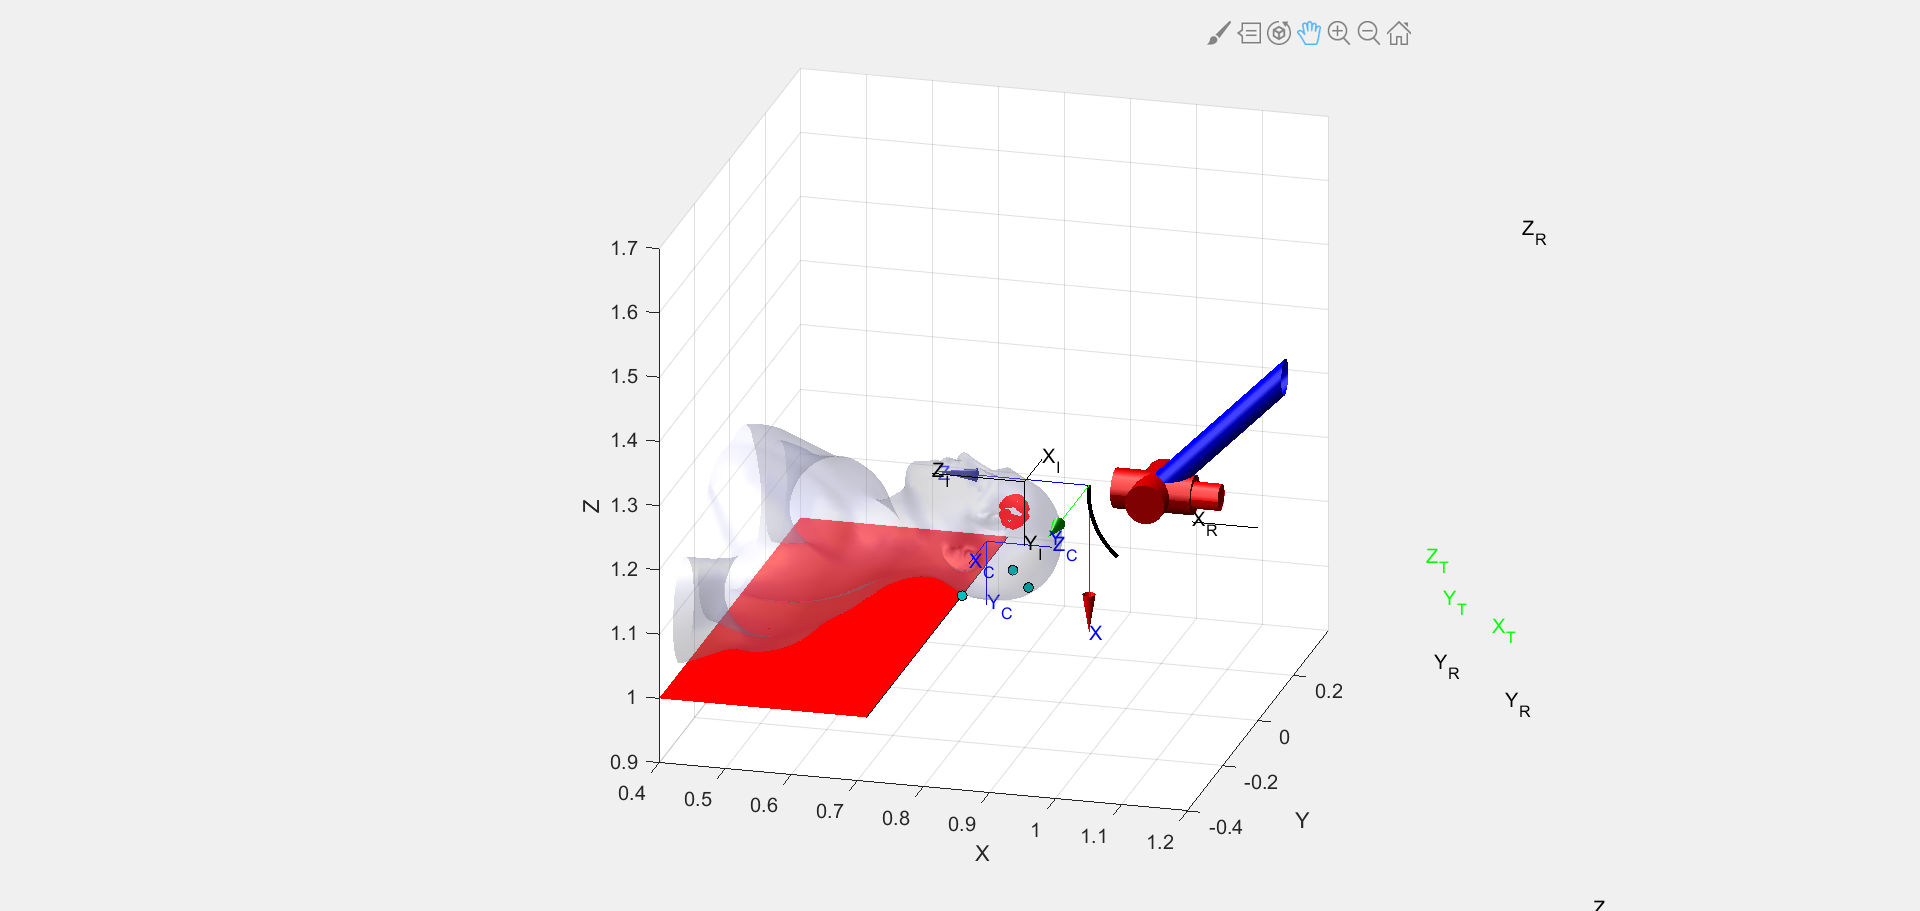

view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7])

% task_changeTool
% task_burningLaser

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

RFR = transl(1.5, -0.2, 1.35) * trotz(120, 'deg');
p560.base = RFR;

%fiducials in robot frame (via p560.teach)
fiducidalsRF = [ 0.4891    0.4631   -0.2725;
                0.5639    0.4668   -0.2715;
                0.4883    0.5638   -0.2755];

AB=(fiducidals(1,:)-fiducidals(2,:))/norm(fiducidals(1,:)-fiducidals(2,:)); % Vector pointing A 
CB=(fiducidals(3,:)-fiducidals(2,:))/norm(fiducidals(2,:)-fiducidals(3,:)); % Vector pointing C
Z_B=cross(CB, AB)/norm(cross(CB, AB)) % Perpendicular to BA & CB equivalent to â; Z point up

Z_B =    -0.0183   -0.0277    0.9995


O_B_A =oa2r(AB, Z_B); % AB is the orientation vector (y axis ô) and Z_B is tha aproach axis (z axis â). The result ^n is in x axis
                
AB_RF=(fiducidalsRF(1,:)-fiducidalsRF(2,:))/norm(fiducidalsRF(1,:)-fiducidalsRF(2,:)); % Vector pointing A 
CB_RF=(fiducidalsRF(3,:)-fiducidalsRF(2,:))/norm(fiducidalsRF(2,:)-fiducidalsRF(3,:)); % Vector pointing C
Z_B_RF=cross(CB_RF, AB_RF)/norm(cross(CB_RF, AB_RF)) % Perpendicular to BA & CB equivalent to â; Z point up

Z_B_RF =    -0.0148    0.0297    0.9995


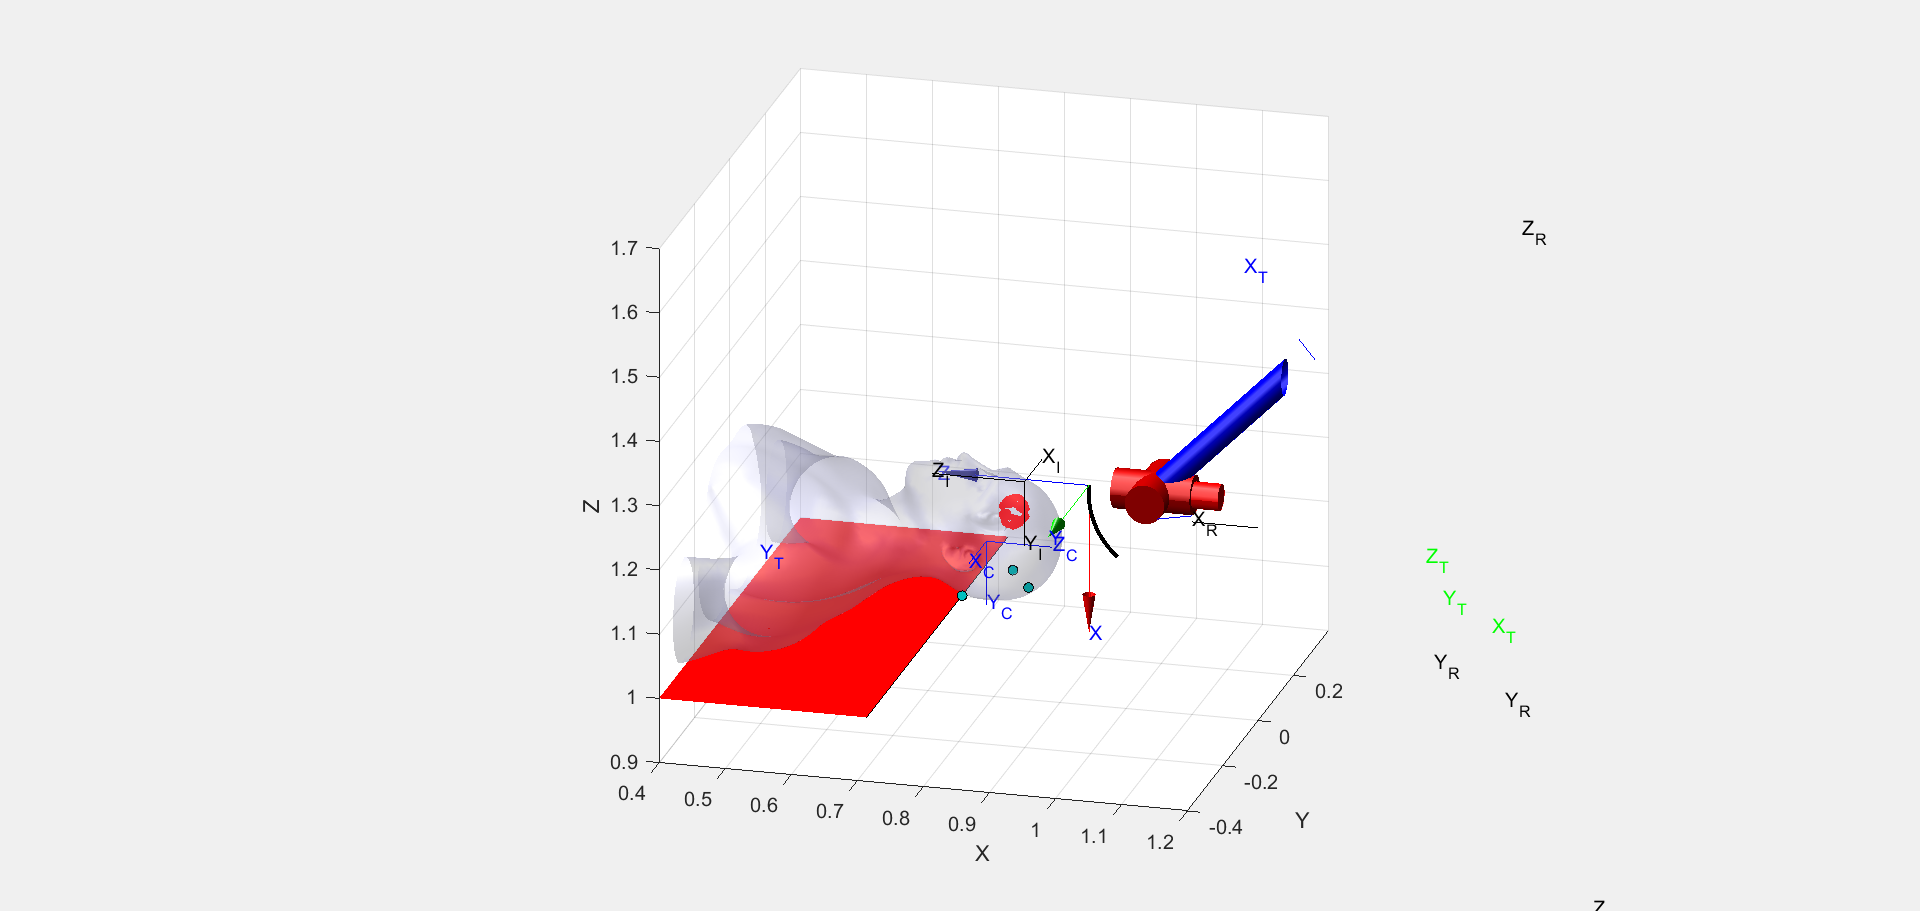

O_B_A_RF =oa2r(AB_RF, Z_B_RF); % AB is the orientation vector (y axis ô) and Z_B is tha aproach axis (z axis â). The result ^n is in x axis

FR = [O_B_A_RF fiducidalsRF(2, :)'; 0 0 0 1];
FN = [O_B_A fiducidals(2, :)'; 0 0 0 1];

R2N = FN*inv(FR);

trplot(R2N, 'length', 1, 'color', 'b', 'frame', 'T')

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

ItoR = inv(R2N) * RFI

ItoR =     0.0009    0.0000    0.0007    0.3701
   -0.0005    0.0000    0.0012    0.5010
    0.0000   -0.0010    0.0000   -0.0625
         0         0         0    1.0000



tumor = load('tumor.csv');

t_even = tumor(1:2:end, :);
t_odd = tumor(2:2:end, :);

t_n1 = [t_even(:, 1) t_odd(:, 2) t_even(:, 3)];
t_n2 = [t_odd(:, 1) t_even(:, 2) t_even(:, 3)];

tumor = [tumor; t_n1; t_n2];

pointR = h2e(ItoR * e2h(tumor'))';

pointWR = h2e(R2N * e2h(pointR'))';
tumor = pointWR;

scatter3(pointR(:, 1), pointR(:, 2), pointR(:, 3), 12, 'r', 'filled')

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

% task_changeTool
% task_biopsy

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

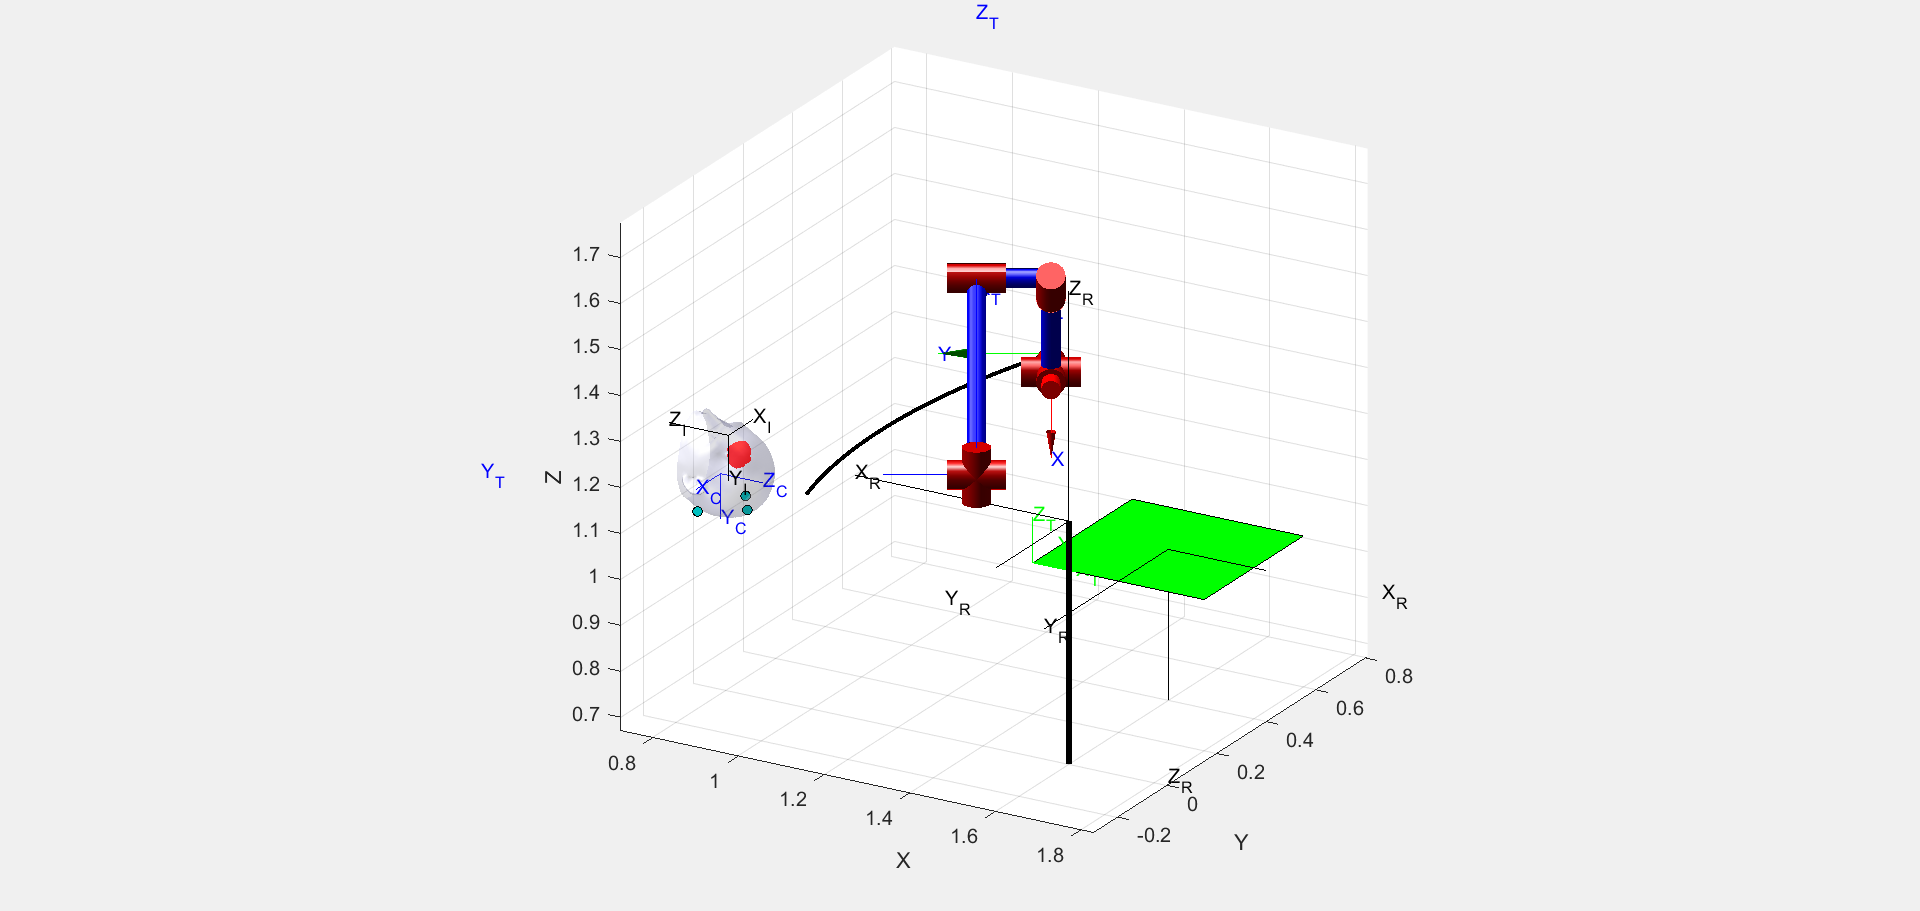

task_changeTool
task_trepanation

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

% task_changeTool
% task_burningLaser